# **HWM Analysis**

#### Using the inbuilt function from a library in MATLAB

%% the result is a 2D vector providing meridional and zonal wind components

w = atmoshwm(-45,-85,25000,'day',150,'seconds',39600,'apindex',80,'model','total','version','14')

w =     3.2874   25.8735


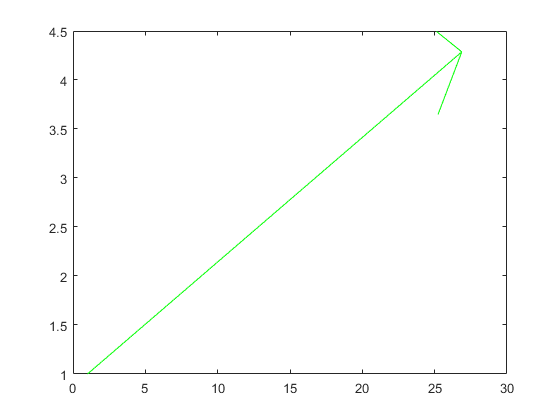

quiver(w(2),w(1),"g", "AutoScale","on","AutoScaleFactor",1)

### PRELIMINARY TRIAL OF HWM MODEL (**DO NOT RUN CELL BELOW**)

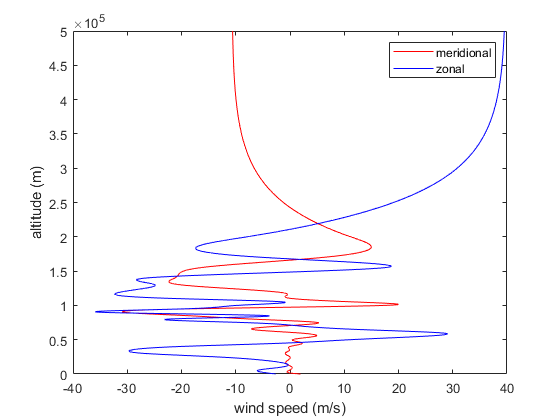

%%% computing altitude vs wind velocity 

latitude = repmat(-6.89,500000,1);
longitude = repmat(-38.56,500000,1);
height = [1:500000];
height = height';
day = repmat(81,500000,1);
seconds = local(6*60*60,longitude); % using the function created 
ap = repmat(12,500000,1);
wind_vel = atmoshwm(latitude,longitude,height,'day',day,'seconds',seconds,'apindex',ap,'model','total','version','14');
plot(wind_vel(:,1), height,"r-", wind_vel(:,2), height, "b-")
xlabel("wind speed (m/s)")
ylabel("altitude (m)")
legend('meridional','zonal')

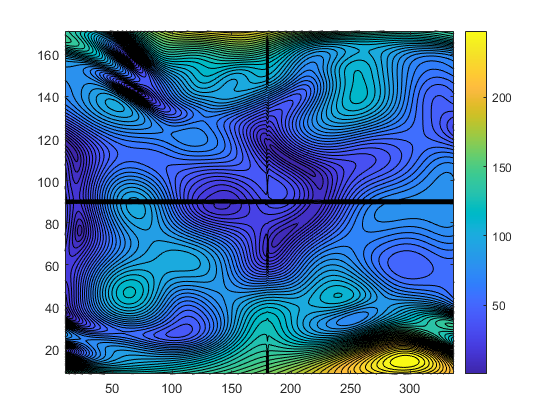


%%% Computing the longitude vs latitude contour maps

lat3 = [1:180];
lon3 = [1:360];
height3 = 250000;
day3 = 81;
seconds3 = 12345;
ap3 = 12;
count = 0;
w_mat1 = nan(180,360);
w_mat2 = nan(180,360);

for i = lat3
    for j = lon3
       wind_vel3 = atmoshwm(i-91,j-181,height3,'day',day3,'seconds',seconds3,'apindex',ap3,'model','total','version','14'); 
       w_mat1(i,j) = wind_vel3(1); %meridional wind matrix
       w_mat2(i,j) = wind_vel3(2); %zonal wind matrix
       count = count +1;
    end
end

cont_wind = sqrt(w_mat1.*w_mat1 + w_mat2.*w_mat2);
contourf(cont_wind, 50)
colorbar

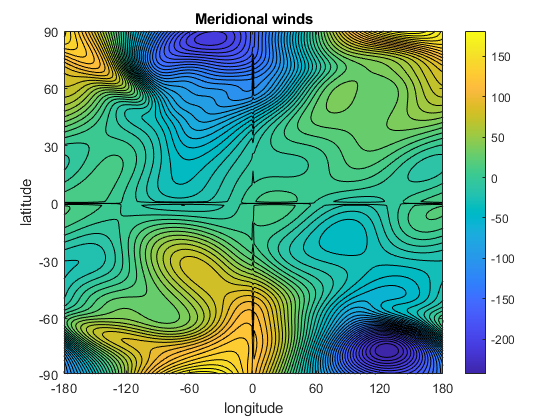


%%% plotting the wind matrices that I have just computed

%%% contour maps of zonal winds
contourf(w_mat1, 50)
xticks([1 60 120 180 240 300 360])
xticklabels({"-180","-120","-60","0","60","120","180"})
yticks([1 30 60 90 120 150 180])
yticklabels({"-90","-60","-30","0","30","60","90"})
colorbar
xlabel("longitude")
ylabel("latitude")
title("Meridional winds")

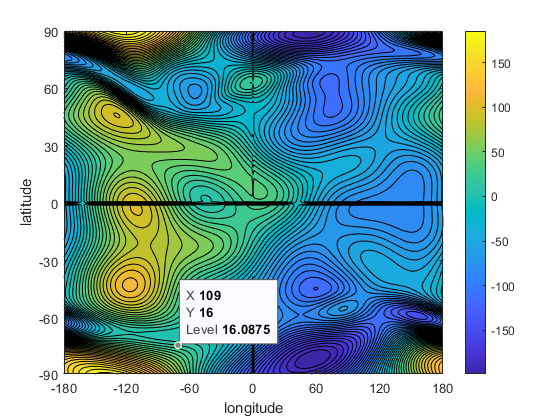



%%% contour maps of meridional winds
contourf(w_mat2, 50)
xticks([1 60 120 180 240 300 360])
xticklabels({"-180","-120","-60","0","60","120","180"})
yticks([1 30 60 90 120 150 180])
yticklabels({"-90","-60","-30","0","30","60","90"})
colorbar
xlabel("longitude")
ylabel("latitude")
hold on;

contour(topo,[90,180],"r")

Unrecognized function or variable 'topo'.

box on
title("Zonal winds")
hold off

%%%%% you might need to flip the matrices %%%%%%

%%% computing a graph of local time vs wind
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CAN WE USE A FUNCTION OR A LOOP TO
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% COMPUTE ALL THESE?
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%

%%% january 

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
day1 = repmat(21, 33946, 1);
ap1 = repmat(12,33946,1);
wind_january = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
day1 = repmat(21, 52454, 1);
ap1 = repmat(12,52454,1);
wind_january0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

%%% february 

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
day1 = repmat(51, 33946, 1);
ap1 = repmat(12,33946,1);
wind_february = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
day1 = repmat(51, 52454, 1);
ap1 = repmat(12,52454,1);
wind_february0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

%%% march

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
day1 = repmat(81, 33946, 1);
ap1 = repmat(12,33946,1);
wind_march = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
day1 = repmat(81, 52454, 1);
ap1 = repmat(12,52454,1);
wind_march0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');


jan = cat(1,wind_january,wind_january0);
plot([1:86400], jan(:,2) ,"b-",[1:86400], jan(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("january")

feb = cat(1,wind_february,wind_february0);
plot([1:86400], feb(:,2) ,"b-",[1:86400], feb(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("february")

mar = cat(1,wind_march,wind_march0);
plot([1:86400], mar(:,2) ,"b-",[1:86400], mar(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("march")

%%% april
time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(111, 33946, 1);
wind_april = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(111, 52454, 1);
wind_april0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

apr = cat(1,wind_april,wind_april0);
plot([1:86400], apr(:,2) ,"b-",[1:86400], apr(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("April")

%%% may

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(141, 33946, 1);
wind_may = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(141, 52454, 1);
wind_may0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

may = cat(1,wind_may,wind_may0);
plot([1:86400], may(:,2) ,"b-",[1:86400], may(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("May")

%%% june

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(171, 33946, 1);
wind_jun = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(171, 52454, 1);
wind_jun0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

jun = cat(1,wind_jun,wind_jun0);
plot([1:86400], jun(:,2) ,"b-",[1:86400], jun(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("June")

%%% july

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(201, 33946, 1);
wind_july = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(201, 52454, 1);
wind_july0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

july = cat(1,wind_july,wind_july0);
plot([1:86400], july(:,2) ,"b-",[1:86400], july(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("July")

%%% august

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(231, 33946, 1);
wind_aug = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(231, 52454, 1);
wind_aug0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

aug = cat(1,wind_aug,wind_aug0);
plot([1:86400], aug(:,2) ,"b-",[1:86400], aug(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("August")

%%% september

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(261, 33946, 1);
wind_sept = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(261, 52454, 1);
wind_sept0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

sept = cat(1,wind_sept,wind_sept0);
plot([1:86400], sept(:,2) ,"b-",[1:86400], sept(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("September")

%%% october

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(291, 33946, 1);
wind_oct = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(291, 52454, 1);
wind_oct0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

oct = cat(1,wind_oct,wind_oct0);
plot([1:86400], oct(:,2) ,"b-",[1:86400], oct(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("October")

%%% nov

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(321, 33946, 1);
wind_nov = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(321, 52454, 1);
wind_nov0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

nov = cat(1,wind_nov,wind_nov0);
plot([1:86400], nov(:,2) ,"b-",[1:86400], nov(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("November")

%%% dec

time = [52455:86400];
time = time';
height1 = repmat(250000, 33946,1);
lat1 = repmat(-6.89,33946,1);
long1 = repmat(-38.56, 33946,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,33946,1);
day1 = repmat(351, 33946, 1);
wind_dec = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time,'apindex',ap1,'model','total','version','14');

time1 = [1:52454];
time1 = time1';
height1 = repmat(250000, 52454,1);
lat1 = repmat(-6.89,52454,1);
long1 = repmat(-38.56, 52454,1);
local_time = local(6*60*60,long1);
ap1 = repmat(12,52454,1);
day1 = repmat(351, 52454, 1);
wind_dec0 = atmoshwm(lat1,long1,height1,'day',day1,'seconds',time1,'apindex',ap1,'model','total','version','14');

dec = cat(1,wind_dec,wind_dec0);
plot([1:86400], dec(:,2) ,"b-",[1:86400], dec(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("December")

%%% subplots 
subplot(4,3,1);
jan = cat(1,wind_january,wind_january0);
plot([1:86400], jan(:,2) ,"b-",[1:86400], jan(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("january")

subplot(4,3,2);
feb = cat(1,wind_february,wind_february0);
plot([1:86400], feb(:,2) ,"b-",[1:86400], feb(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("february")

subplot(4,3,3);
mar = cat(1,wind_march,wind_march0);
plot([1:86400], mar(:,2) ,"b-",[1:86400], mar(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("march")

subplot(4,3,4);
apr = cat(1,wind_april,wind_april0);
plot([1:86400], apr(:,2) ,"b-",[1:86400], apr(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("April")

subplot(4,3,5);
may = cat(1,wind_may,wind_may0);
plot([1:86400], may(:,2) ,"b-",[1:86400], may(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("May")

subplot(4,3,6);
jun = cat(1,wind_jun,wind_jun0);
plot([1:86400], jun(:,2) ,"b-",[1:86400], jun(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("June")

subplot(4,3,7);
july = cat(1,wind_july,wind_july0);
plot([1:86400], july(:,2) ,"b-",[1:86400], july(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("July")

subplot(4,3,8);
aug = cat(1,wind_aug,wind_aug0);
plot([1:86400], aug(:,2) ,"b-",[1:86400], aug(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("August")

subplot(4,3,9);
sept = cat(1,wind_sept,wind_sept0);
plot([1:86400], sept(:,2) ,"b-",[1:86400], sept(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("September")

subplot(4,3,10);
oct = cat(1,wind_oct,wind_oct0);
plot([1:86400], oct(:,2) ,"b-",[1:86400], oct(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("October")

subplot(4,3,11);
nov = cat(1,wind_nov,wind_nov0);
plot([1:86400], nov(:,2) ,"b-",[1:86400], nov(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("November")

subplot(4,3,12);
dec = cat(1,wind_dec,wind_dec0);
plot([1:86400], dec(:,2) ,"b-",[1:86400], dec(:,1), "r" );
legend('zonal','meridional')
xlabel("Local time (s)")
ylabel("Wind speed (m/s)")
title("December")


## END OF PRILIMINARY TRIAL

#### HWM winds speeds along the trajectory of the Cubesat

%%% plotting all the trajectories from each day

cd ("C:\Users\rifat\OneDrive - University College London\Rifat's PC\Internship 2021\Rifat's project\CorrectINMSdata"); %path

%%% 27th of may
w27m = atmoshwm(-49.4901,-46.2051, 369719.9,'day', 146, 'seconds',34990.74, 'apindex',3.0,'model','total','version','14')

w27m =    20.7044 -118.3853


%%% 28th of may 
w28m = atmoshwm(-51.2,-47.9579, 369696.5,'day', 147, 'seconds',36791.28, 'apindex',4.0,'model','total','version','14')

w28m =    10.6156 -124.1822


%%% 28th of june 
w28j = atmoshwm(-48.41,124.501, 369696.5,'day', 178, 'seconds',32580, 'apindex',5.0,'model','total','version','14')

w28j =   -34.2411   95.3110


%%% 1st of july
w1jl = atmoshwm(-30.45,122.39, 362735.7,'day', 181, 'seconds',20427, 'apindex',2.0,'model','total','version','14')

w1jl =   -58.7380  -16.9715


Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4229 double]
              YData: [1×4229 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


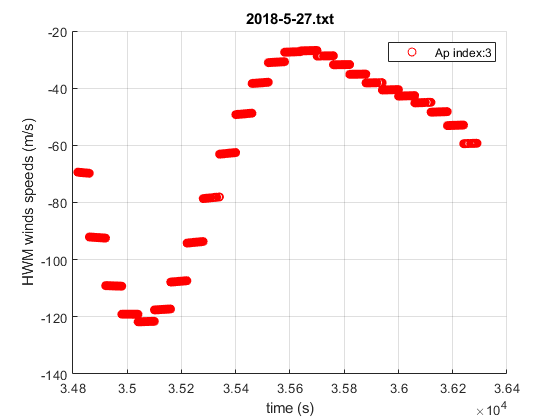

wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4229 double]
              YData: [1×4229 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties



[wind_vs_time] = hwm_alongpath_time("2018-5-27.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4191 double]
              YData: [1×4191 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


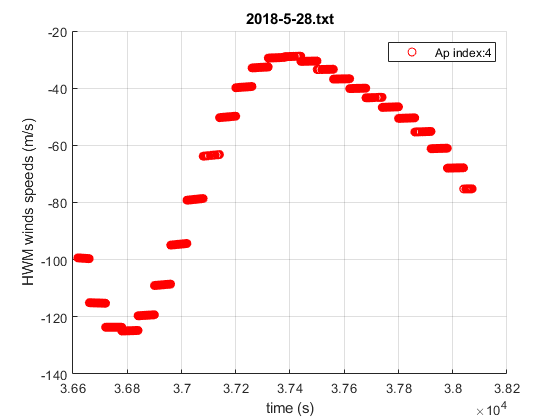

wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4191 double]
              YData: [1×4191 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


[wind_vs_time] = hwm_alongpath_time("2018-5-28.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4224 double]
              YData: [1×4224 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


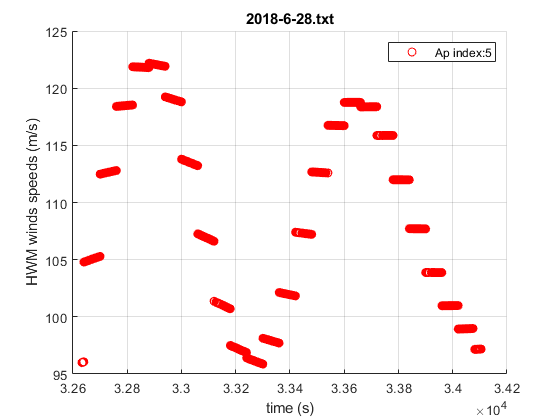

wind_vs_time =   Scatter (Ap index:5) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4224 double]
              YData: [1×4224 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


[wind_vs_time] = hwm_alongpath_time("2018-6-28.txt",5)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4242 double]
              YData: [1×4242 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


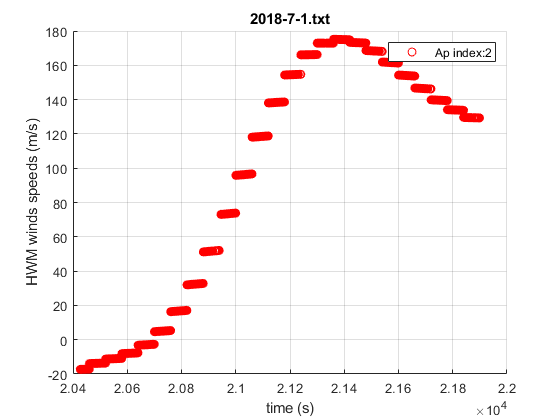

wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4242 double]
              YData: [1×4242 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


[wind_vs_time] = hwm_alongpath_time("2018-7-1.txt",2)

#### Creating subplots comparing winds speeds for day and night

%%% plotting the zonal speed of the wind speeds along the cubesat path

%% These are analogous to the INMS subplots
%% The hwm subplots will be compared to the INMS subplots

%% initialising figure

figure;
graph = tiledlayout(2,9);
title(graph,'HWM zonal winds vs Time');

% day side

ax1 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-19.txt",2)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4226 double]
              YData: [1×4226 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4226 double]
              YData: [1×4226 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax2 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-21.txt",2)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax3 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-22.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4231 double]
              YData: [1×4231 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4231 double]
              YData: [1×4231 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax4 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-23.txt",8)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:8) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax5 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-25.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4241 double]
              YData: [1×4241 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4241 double]
              YData: [1×4241 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax6 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-26.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax7 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-27.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4229 double]
              YData: [1×4229 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4229 double]
              YData: [1×4229 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax8 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-28.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4191 double]
              YData: [1×4191 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4191 double]
              YData: [1×4191 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax9 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-29.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties



% night side

ax18 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-12.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4202 double]
              YData: [1×4202 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4202 double]
              YData: [1×4202 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax10 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-13.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4207 double]
              YData: [1×4207 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4207 double]
              YData: [1×4207 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax11 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-20.txt",5)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:5) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax12 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-23.txt",18)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:18) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax13 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-24.txt",6)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:6) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax14 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-25.txt",12)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:12) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax15 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-26.txt",20)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:20) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax16 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-28.txt",5)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4224 double]
              YData: [1×4224 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:5) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4224 double]
              YData: [1×4224 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax17 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-7-1.txt",2)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4242 double]
              YData: [1×4242 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4242 double]
              YData: [1×4242 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


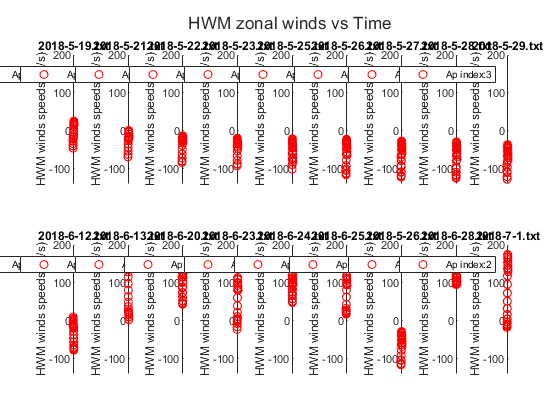


%%% same scale between all subplots
linkaxes([ax1 ax2 ax3 ax4 ax5 ax6 ax7 ax8 ax9 ax10 ax11 ax12 ax13 ax14 ax15 ax16 ax17 ax18], "y")


%%%%%%%%%%%% subplots for the zonal winds is saved in project file %%%%%%%%%% 

%%% plotting the magnitude of the wind speeds along the cubesat path

%% initialising figure
figure;
graph = tiledlayout(2,9);
title(graph,'Magnitude of HWM winds vs Time');

% day side

ax1 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-19.txt",2)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4226 double]
              YData: [1×4226 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4226 double]
              YData: [1×4226 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax2 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-21.txt",2)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax3 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-22.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4231 double]
              YData: [1×4231 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4231 double]
              YData: [1×4231 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax4 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-23.txt",8)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:8) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax5 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-25.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4241 double]
              YData: [1×4241 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4241 double]
              YData: [1×4241 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax6 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-26.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax7 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-27.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4229 double]
              YData: [1×4229 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4229 double]
              YData: [1×4229 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax8 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-28.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4191 double]
              YData: [1×4191 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4191 double]
              YData: [1×4191 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax9 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-29.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties



% night side

ax18 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-12.txt",3)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4202 double]
              YData: [1×4202 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:3) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4202 double]
              YData: [1×4202 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax10 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-13.txt",4)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4207 double]
              YData: [1×4207 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:4) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4207 double]
              YData: [1×4207 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax11 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-20.txt",5)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:5) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax12 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-23.txt",18)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:18) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax13 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-24.txt",6)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:6) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4236 double]
              YData: [1×4236 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax14 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-25.txt",12)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:12) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4240 double]
              YData: [1×4240 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax15 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-5-26.txt",20)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:20) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4233 double]
              YData: [1×4233 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax16 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-6-28.txt",5)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4224 double]
              YData: [1×4224 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:5) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4224 double]
              YData: [1×4224 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


ax17 = nexttile;
[wind_vs_time] = hwm_alongpath_time("2018-7-1.txt",2)

Plotting hwm winds vs time for a chosen day along CubeSat directory


wind_vs_time =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4242 double]
              YData: [1×4242 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


wind_vs_time =   Scatter (Ap index:2) with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1×4242 double]
              YData: [1×4242 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


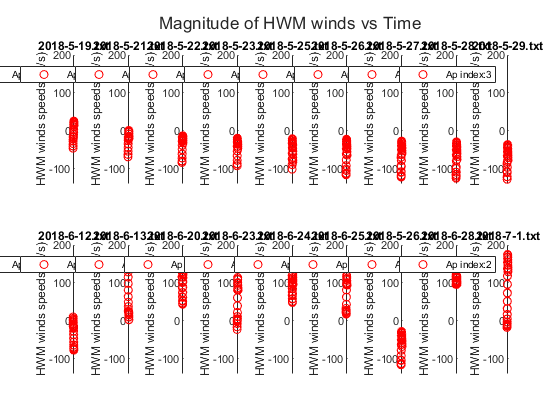

w21 =   -82.5185  -43.9042


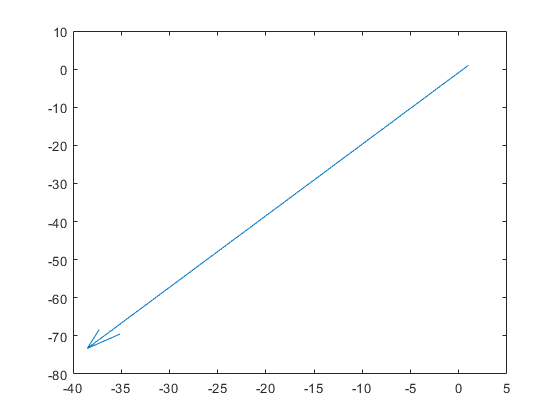

w23 =   -78.9735  -40.5819


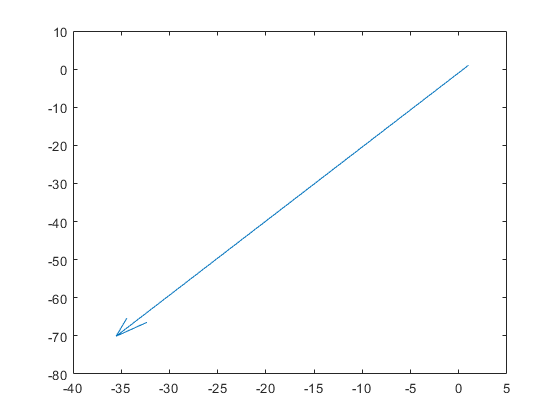

w26 =   -27.9234 -103.7107


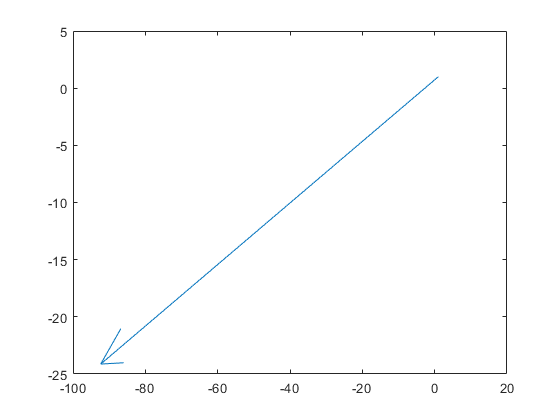

w27 =    20.6577 -118.3858


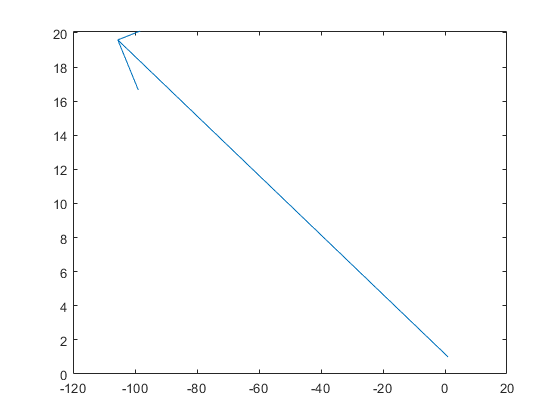

w28 =    10.5476 -124.0967


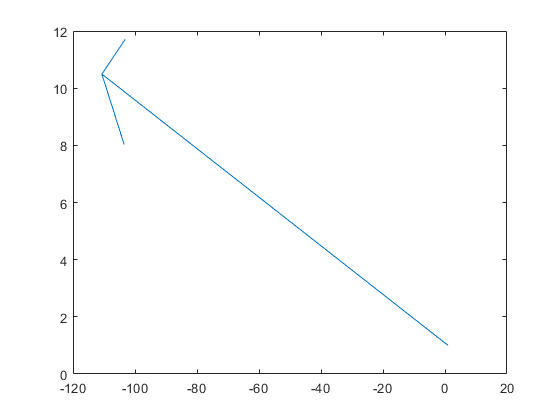

w29 =    52.1937  -85.0088


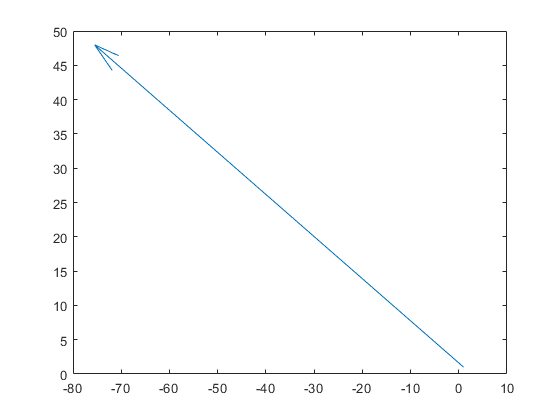

w13 =    29.3274   85.9872


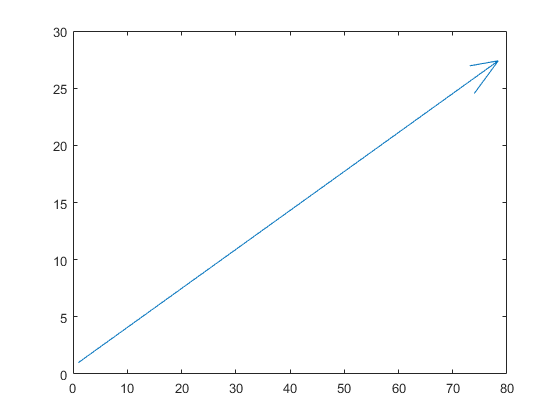


%%% same scale between all subplots
linkaxes([ax1 ax2 ax3 ax4 ax5 ax6 ax7 ax8 ax9 ax10 ax11 ax12 ax13 ax14 ax15 ax16 ax17 ax18], "y")
hold off

#### Inspecting the direction of the wind speed at INMS peak count

%%% plotting HWM vector at INMS peak count for certain dates

% 21-may
figure();
w21 = atmoshwm(-51.02,-50.25, 370353.7,"day", 140, 'seconds',46991, 'apindex',2,'model','total','version','14')

w21 =   -82.5185  -43.9042


quiver(w21(2),w21(1))


% 223-may
w23 = atmoshwm(-51.6,-17.3, 369890.1,"day", 142, 'seconds',39494, 'apindex',8,'model','total','version','14')

w23 =   -78.9735  -40.5819


quiver(w23(2),w23(1))


% 26-may
w26 = atmoshwm(-51.32,-43.08, 369890.1,"day", 145, 'seconds',38963, 'apindex',3.0,'model','total','version','14')

w26 =   -27.9234 -103.7107


quiver(w26(2),w26(1))


% 27-may
w27 = atmoshwm(-49.49,-46.20, 369719.9,"day", 146, 'seconds',34994, 'apindex',3.0,'model','total','version','14')

w27 =    20.6577 -118.3858


quiver(w27(2),w27(1))


%28-may
w28 = atmoshwm(-51.18,-47.95, 369696.5,'day', 147, 'seconds',36791.28, 'apindex',4.0,'model','total','version','14')

w28 =    10.5476 -124.0967


quiver(w28(2),w28(1))


%29-may
w29 = atmoshwm(-47.82, -55.98, 369325.3,'day', 148, 'seconds',32781, 'apindex',3,'model','total','version','14')

w29 =    52.1937  -85.0088


quiver(w29(2),w29(1))


%13-jun
w13 = atmoshwm(-38.6, 133.3, 365361.5,'day', 164, 'seconds',49989, 'apindex',3,'model','total','version','14')

w13 =    29.3274   85.9872


quiver(w13(2),w13(1))

#### Creating maps of the HWM vector field with overlaid Cubesat trajectory

%%% wind vector fields for eah day with trajectory

cd ("C:\Users\rifat\OneDrive - University College London\Rifat's PC\Internship 2021\Rifat's project\CorrectINMSdata");

%% initialising figure

% day side
disp("Day side")

Day side


Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


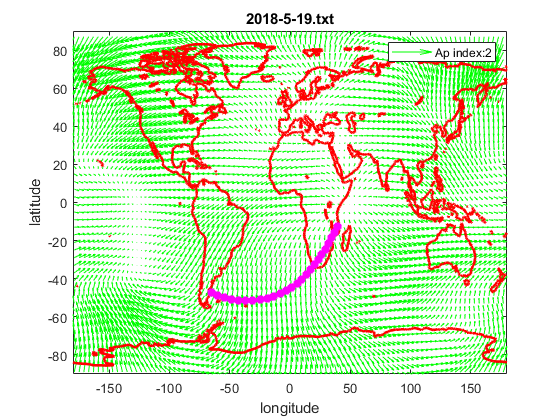

vector_field =   Quiver (Ap index:2) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


[vector_field] = HWM_vectorfield("2018-5-19.txt",2)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


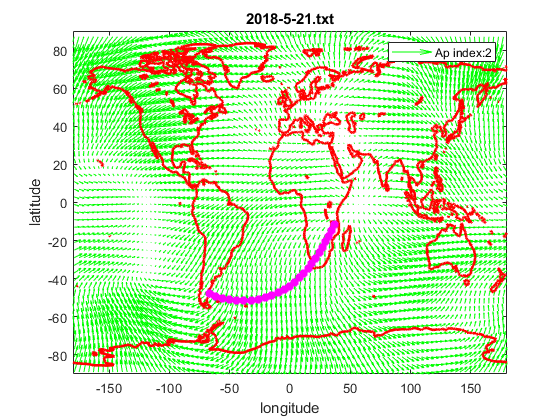

vector_field =   Quiver (Ap index:2) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-21.txt",2)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


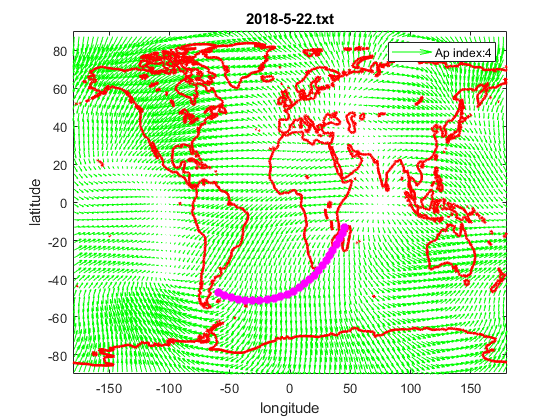

vector_field =   Quiver (Ap index:4) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-22.txt",4)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


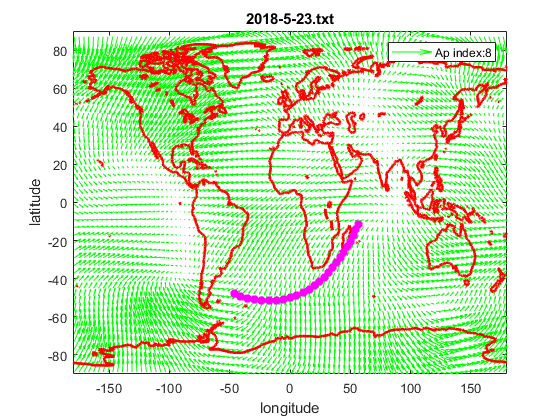

vector_field =   Quiver (Ap index:8) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-23.txt",8)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


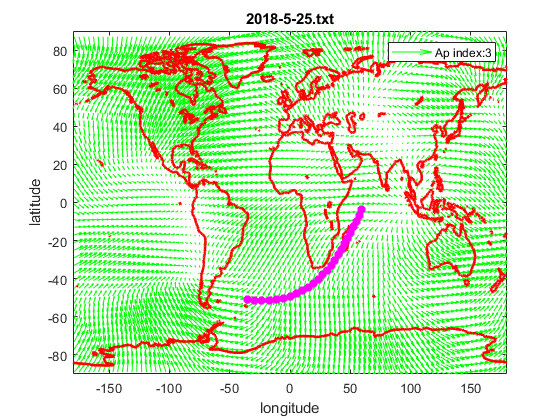

vector_field =   Quiver (Ap index:3) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-25.txt",3)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


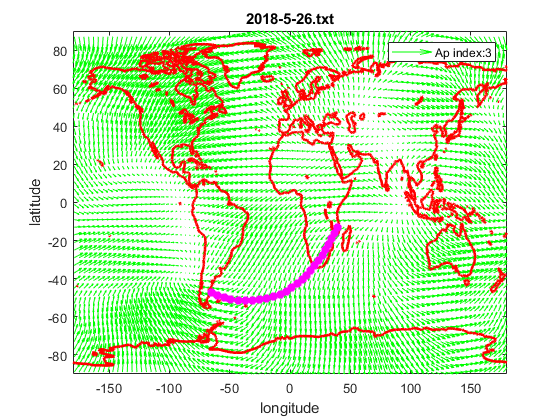

vector_field =   Quiver (Ap index:3) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-26.txt",3)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


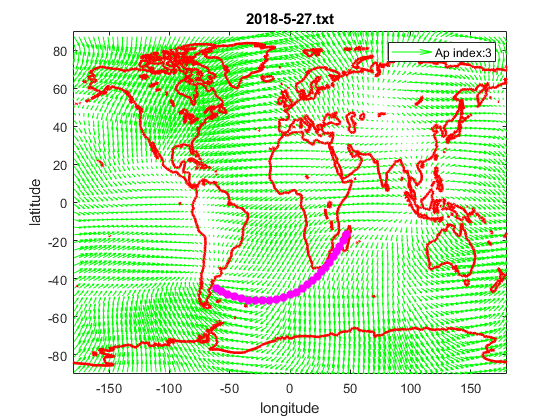

vector_field =   Quiver (Ap index:3) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-27.txt",3)


[vector_field] = HWM_vectorfield("2018-5-28.txt",4)

Plotting HWM wind vector field for each day


vector_field =   Quiver with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties


vector_field =   Quiver (Ap index:4) with properties:

        Color: [0 1 0]
    LineStyle: '-'
    LineWidth: 0.5000
        XData: [180×360 double]
        YData: [180×360 double]
        ZData: []
        UData: [180×360 double]
        VData: [180×360 double]
        WData: []

  Show all properties



[vector_field] = HWM_vectorfield("2018-5-29.txt",3)

Plotting HWM wind vector field for each day



% night side

disp("Night side")
[vector_field] = HWM_vectorfield("2018-6-12.txt",3)

[vector_field] = HWM_vectorfield("2018-6-13.txt",4)

[vector_field] = HWM_vectorfield("2018-6-20.txt",5)

[vector_field] = HWM_vectorfield("2018-6-23.txt",18)

[vector_field] = HWM_vectorfield("2018-6-24.txt",6)

[vector_field] = HWM_vectorfield("2018-6-25.txt",12)

[vector_field] = HWM_vectorfield("2018-6-26.txt",20)

[vector_field] = HWM_vectorfield("2018-6-28.txt",5)

[vector_field] = HWM_vectorfield("2018-7-1.txt",2)

#### Final calculations to find the angle between the INMS look direction and HWM wind vector at INMS peak count location

%%% calculations to investigate the direction of the wind vectors %%%

disp("Calculations to investigate the direction of the wind vectors with respect to INMS")

Calculations to investigate the direction of the wind vectors with respect to INMS


disp("")

% 29th of May 
disp("---29th of May---")

---29th of May---


w29 % HWM wind vector at high geometric factor peak's location and time

w29 =    52.1937  -85.0088


norm(w29) 

ans = 99.7531

atand(w29(1)/w29(2)) % finding the angle between the HWM vector components 

ans = -31.5491

y = -47.82 - -49.18 

y = 1.3600

x = -55.98 - -50.69

x = -5.2900

atand(y/x) % finding the angle of the INMS's look direction

ans = -14.4179

disp("Angle between INMS look direction and wind vector field")

Angle between INMS look direction and wind vector field


atand(w29(1)/w29(2)) - atand(y/x) % difference between the HWM direction and INMS look direction 

ans = -17.1312

%not in field of view

disp("")
% 28th of May
disp("---28th of May---")

---28th of May---


w28

w28 =    10.5476 -124.0967


norm(w28j)

ans = 101.2751

atand(w28(1)/w28(2))

ans = -4.8582

y = -49.48 - -50.48

y = 1

x = -59.43 - -53.80

x = -5.6300

atand(y/x)

ans = -10.0718

disp("Angle between INMS look direction and wind vector field")

Angle between INMS look direction and wind vector field


atand(w28(1)/w28(2)) - atand(y/x) %not in field of view

ans = 5.2136


disp("")
% 27th of May
disp("---27th of May---")

---27th of May---


w27

w27 =    20.6577 -118.3858


norm(w27)

ans = 120.1746

atand(w27(1)/w27(2))

ans = -9.8981

y = -48.20 - -49.49

y = 1.2900

x = -51.57 - -46.20

x = -5.3700

atand(y/x)

ans = -13.5078

disp("Angle between INMS look direction and wind vector field")

Angle between INMS look direction and wind vector field


atand(w27(1)/w27(2)) - atand(y/x) %not in field of view

ans = 3.6097


disp("")
% 26th of May
disp("---26th of May---")

---26th of May---


w26

w26 =   -27.9234 -103.7107


norm(w26)

ans = 107.4040

atand(w26(1)/w26(2))

ans = 15.0692

y = -50.72 - -51.32

y = 0.6000

x = -48.98 - -43.08

x = -5.9000

atand(y/x)

ans = -5.8067

disp("Angle between INMS look direction and wind vector field")

Angle between INMS look direction and wind vector field


atand(w26(1)/w26(2)) - atand(y/x) %not in field of view

ans = 20.8759